% 先尝试L=3，也即共有N=2^(3*3)=512种颜色
L = 4;
N = 2^(3*L);    % 颜色数

v = zeros(N,1);
for i = 1:1:33
    img = double(imread(['Faces\',num2str(i),'.bmp']));
    [H,W,~] = size(img);
    num_pix = H*W;
    
    u = zeros(N,1);
    for j = 1:1:H
        for k = 1:1:W
            color=img(j,k,:);
            R = floor(color(1)/2^(8-L));
            G = floor(color(2)/2^(8-L));
            B = floor(color(3)/2^(8-L));
            n = R*2^(2*L)+G*2^L+B;
            u(n+1) = u(n+1)+1;
        end
    end
    u = u/num_pix;
    v = v + u;
    
end
v = v/33;

v_2 = v;

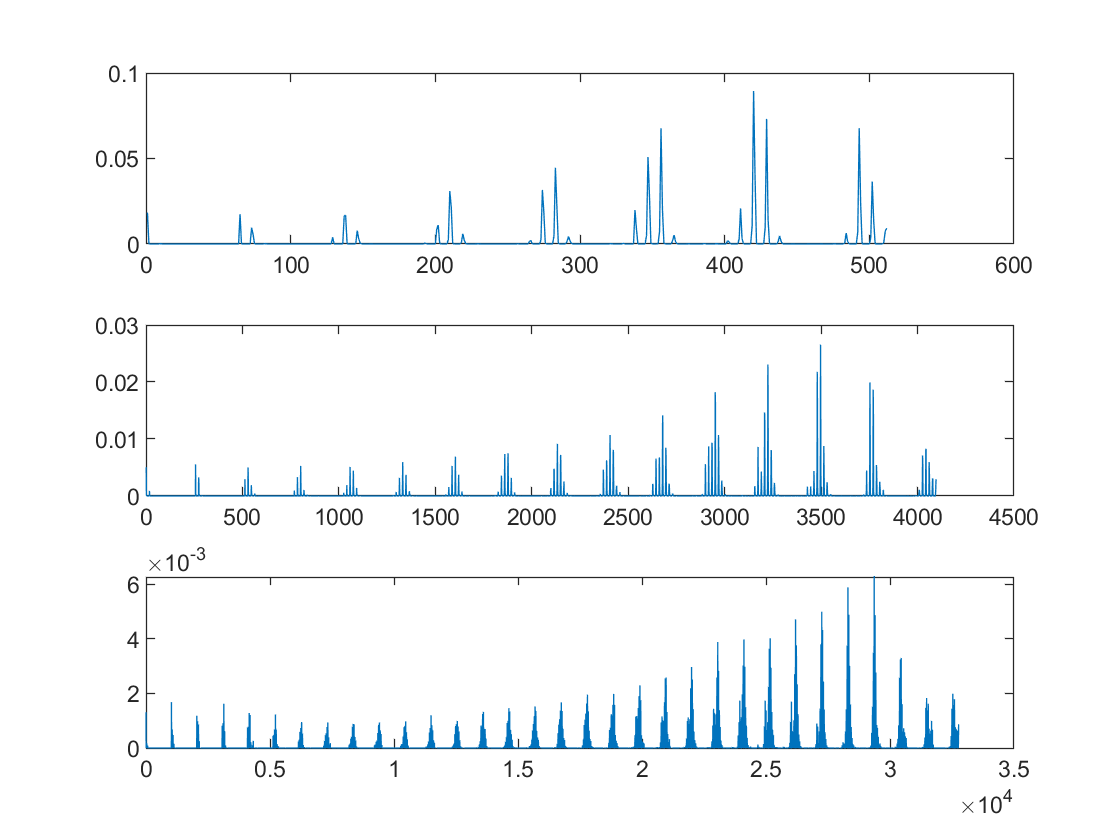

x1 = 1:512;
x2 = 1:4096;
x3 = 1:32768;
subplot(3,1,1);
plot(x1,v_1);
subplot(3,1,2);
plot(x2,v_2);
subplot(3,1,3);
plot(x3,v_3);

save('v',"v_1","v_2","v_3");